WLG_st.name='WLG'; 
WLG_st.lat=36.29;
WLG_st.lon=100.90;
WLG_st.alt=3810;
WLG_st.env='Mt';
WLG_st.footp='Mix';

WLG_rd=read_betsy('wlg_2005_2019',WLG_st.name);

datevec(WLG_rd.Time(1))

ans =         2005           5           6           0           0           0


datevec(WLG_rd.Time(end))

ans =         2019           7          24           0           0           0


  prctile(WLG_rd.U0_S11,[5 50 95])

ans =          0    8.6000   23.2700


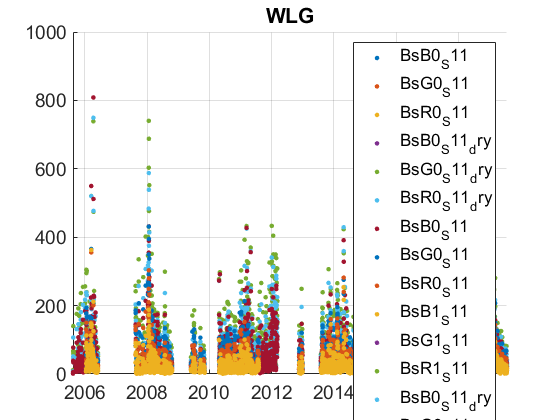

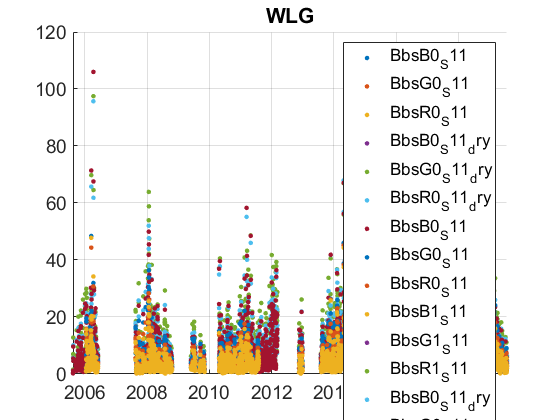

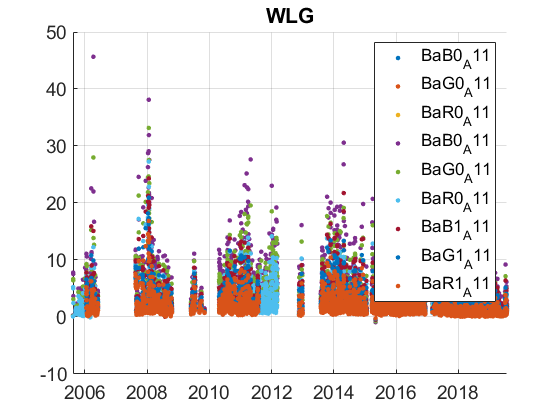

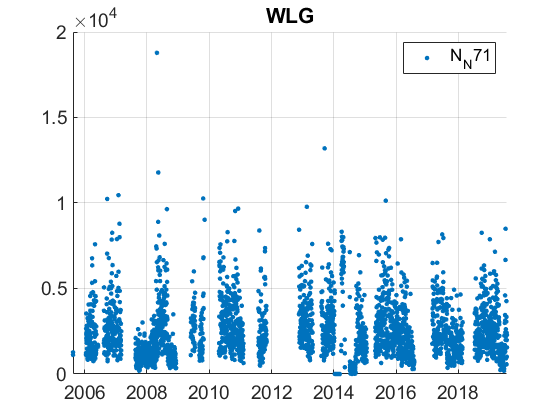

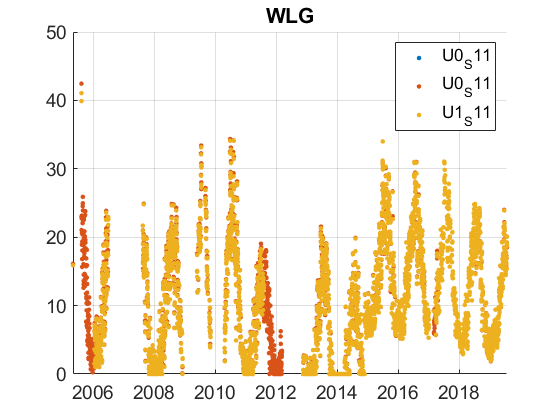

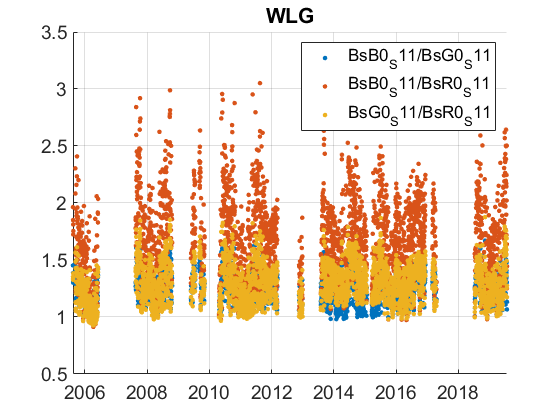

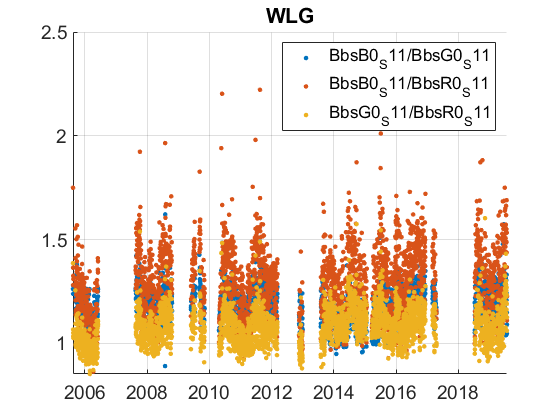

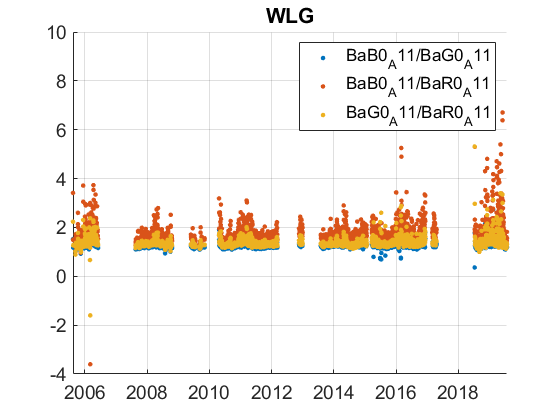

plotFigControl(WLG_rd,WLG_st.name);

% 2 size cut, since 2006
% sc: ok, clear seasonal cycle in summer, 
% abs: 2 size cut,seasonal cycle
%Bs/N and Ba/N: clear seasonal cycle

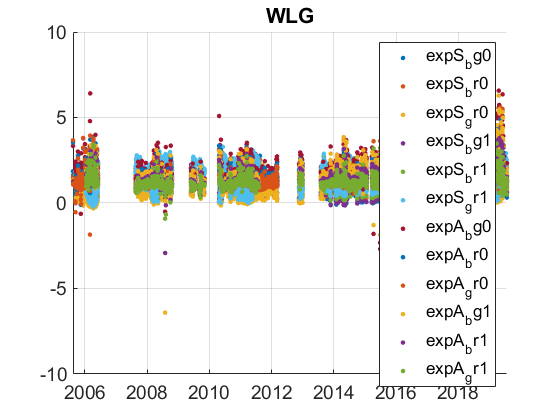

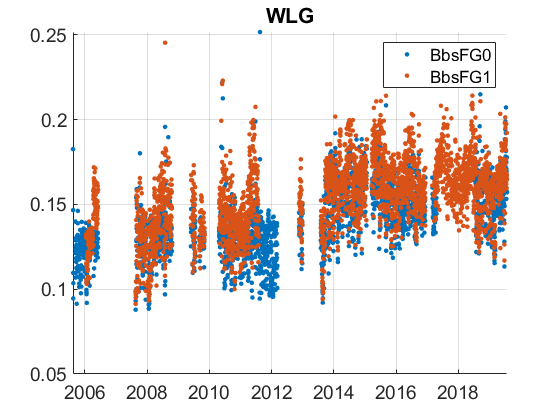

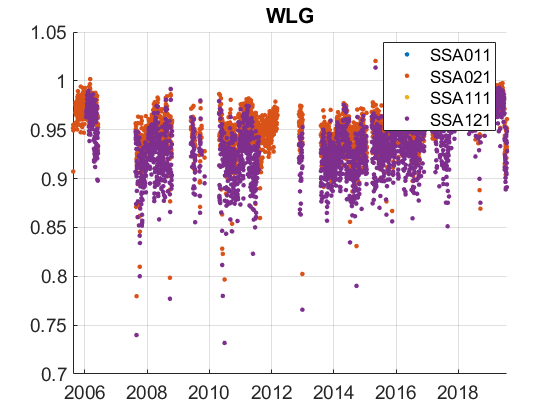

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
WLG_cal=compute_exp_SSA(WLG_rd,lambdaSC, lambdaAE);
plotFigControl_cal(WLG_cal, WLG_st.name);

%Questions:
%problems:
%U not cte:higher in 2009-2010 and then from 28.11.2014: why ?
 %scat: a lot of holes: complete year: true;2011, 2014-2016 not much
 %scat and bscat: end of 2007: strange with few high values.
 % best way woul be 30.8.2007 to july 2019: first and last y complete: but
 % how to use the automatic  end_year thereafter ?
 %scatPM10: hole in 2017-2018
 %scat PM1: end y == 2018 possible
 % --> use PM1 only ?
 
 %abs: same holes than scat (also PM10 ?) 2008-2018 ? or better 2008-2016 ?
 %abs: decrease of both min and max in 2017: real ?
 
 % abs ratio: higher ration since end of october 2018: any reason ?
 % SSA: too high in 2006, too low at the end of 2007, rapid higher change
 % at the end of December 2015, rapid decrease in June 2019: reasons ?
 
 %N: strange at the end of 2007-begin of 2008, too low values 10.5-10.9
 %2014, kind of a break point in september 2017, idem in July 2019

WLG_tr=WLG_rd;
WLG_tr.y=year(WLG_tr.Time);
% begin at the beginning of a almost complete year:2008
%end: 2018 for  PM1, and 2016 for PM10 
P=timerange('2008-01-01','2019-01-01');
WLG_tr=WLG_tr(P,:);

%no RH trend and no dry trend

names=fieldnames(WLG_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U_";"U1";"U0";"BbsB_";"BbsG_";"BbsR_"]) |  contains(names,["Q","dry"]);
N=names(c);
for i=1:length(N)
    WLG_tr.(N{i})=[];
end

names=fieldnames(WLG_tr);
P2=timerange('2017-01-01','2019-01-01');
c=contains (names,["0"]);
N=names(c);
for i=1:length(N)
    WLG_tr.(N{i})(P2)=NaN;
end 


WLG_cal2=compute_exp_SSA(WLG_tr,lambdaSC, lambdaAE);


%expS and BbsF eventually 2008-2018, but only 2014-2018 is really ok : wait
%for answer

% %expA (2008-2015): too short: trend on BG  only
WLG_cal2.expS_br0=[];
WLG_cal2.expS_gr0=[];
WLG_cal2.expS_br1=[];
WLG_cal2.expS_gr1=[];

WLG_cal2.expA_br0=[];
WLG_cal2.expA_gr0=[];
WLG_cal2.expA_br1=[];
WLG_cal2.expA_gr1=[];


WLG_tr=outerjoin(WLG_tr, WLG_cal2);

%trend calculated only on G for neph + abs
WLG_tr.BsB0_S11=[];
WLG_tr.BsB1_S11=[];
WLG_tr.BsR0_S11=[];
WLG_tr.BsR1_S11=[];
WLG_tr.BbsB0_S11=[];
WLG_tr.BbsB1_S11=[];
WLG_tr.BbsR0_S11=[];
WLG_tr.BbsR1_S11=[];

WLG_tr.BaB0_A11=[];
WLG_tr.BaB1_A11=[];
WLG_tr.BaR0_A11=[];
WLG_tr.BaR1_A11=[];

% use expS_bg that seems the most stable

WLG_result= all_trend_STN(WLG_tr,WLG_st); 


 % --> use PM1 only ?
 %doubt on possible rupture in abs in 2017 ?
 %bbsF and expS and expA: a lot of holes, take with caution 
WLG_result_D=WLG_result;
